# `MATLAB基础教程`

`作者：To_Fourier`

`创建时间：2020年7月26日20：57`

`修改时间：2020年7月28日8：47`

`个人博客：`[`https://qiuming.blog.csdn.net/`](https://qiuming.blog.csdn.net/)

`GitHub：`[`https://github.com/QiuMingZS`](https://github.com/QiuMingZS)

# `MATLAB概述`

`1.命名：`

`MATLAB = MATrix + LABoratory`

`2.运行平台：`

`Windows, Linux, MacOS`

`3.特点：`

`    1）强大的数值运算功能；`

`    2）强大的图形处理能力；`

`    3）高级但简单的编程环境；`

`    4）丰富的工具箱`

`4.视窗可视化环境`

`    * 标题栏（Title Bar）`

`    * 菜单（Menu）`

`    * 工具栏（ToolBar）`

`    * 视图一：current directory/workspace`

`    * 视图二：command window `

`    * 视图三：command history`

# `Command Window`

`1.命令提示符 >>`

`2.上下左右箭头, Home, End, Delete, Insert`

`3.清空命令行窗口`

clc

`4.清空工作区`

clear

`5.查看帮助`

help sin

`6.查找`

% lookfor sin

`7.查看相关文档`

doc sin

`8.分号取消输出`

a = 5;

`9.续行符`

b = 1 + 2 + 3 + ...
    5 + 6

`10.命令之间的逗号`

c = 5, d = 6

`11.查看MATLAB搜索路径`

path

`12.CTRL + C强制终止`

`13.退出MATLAB`

% exit
% quit
% 直接关闭

# `一个简单的例子`

`要求：`

`编写函数文件arith_1.m，任意输入一个正整数，如果是1，直接输出1。`

`否则：如果是偶数，用2除，如果是奇数，用3乘再加1，反复这个过程，直到所得到的数为1，将依次得到的这个数列返回（数列中包括输入的正整数）`

`代码示例：`

arith_1(65)

# `MATLAB的工作空间`

`  * 当MATLAB启动后，系统会自动建立一个工作空间，这时的工作空间内只包含系统所提供的一些特殊变量，如pi，eps，nan，i等。`

`  * 随着用户的使用，逐渐增加一些用户自己定义的变量。`

`  * 使用who，whos可以查看到当前工作空间所有变量的情况。`

`  * 使用clear可以删除全部或部分工作空间中的变量。`

`  * 关闭MATLAB，释放工作空间，所有变量会被释放。`

# `MATLAB的搜索路径`

path

`MATLAB遇到一个命令（test）时，其处置过程为： `

`    1.将test视为使用者自定义的变量。 `

`    2.若test不是使用者自定义的变量，将其视为系统定义的常量。 `

`    3.若test不是常量，检查其是否为当前工作目录下的M文件。 `

`    4.若不是，则由搜寻路径寻找是否有test.m的文件。 `

`    5.若在搜寻路径中找不到，则MATLAB会印出错误讯息。`

`    * 处置过程可能因版本不同而略有不同。  `

# `变量`

`MATLAB特殊之处(相较于C语言)：无需进行变量声明。`

`* 遇到新变量名时，自动生成变量，并指定合适的存储空间。`

`* 如变量早已存在，则自动更新。`

## `1.系统特殊变量 `

% ans
1 + 2 + 3 + 4 + 5

% 其他的系统特殊变量
pi
inf
eps
nan
NaN
i
j

## `2.变量命名规则`

`* 变量名由字母、数字和下划线组成。`

`* 字母间不可留空格且第一个字符必须为字母`

`* 区分大小写。`

`* 变量名的长度上限为n个字符。`

`* 变量名不能为中文；`

`* 系统变量名不要和自定义重名。`

`万一自定义变量名和系统变量名一样结果会怎样？怎么办?`

isvarname  myVarName  
isvarname  7myVarName

## `3.获取当前变量`

`命令行直接键入变量名。`

a = 5;
a

## `4.变量的精度`

`控制显示精度函数： format`

`控制精度计算的函数：`

`    digits(n):设置缺省的精度；`

`    vpa(S,n):将S表示为n位有效位数的形式。`

x = 0;
for n = 1:82
    x = x + 0.01;
end
x == 0.82  
format long
x
   
x=0;
for n = 1:82
    x = x + 1;
end
x == 82

## `5.查看变量`

`who：查看当前工作区（workspace）的变量。`

`whos：查看当前变量的详细信息。`

## `6.清除变量`

`clear：清除所有定义过的变量。`

`clear 变量名：清除某个变量。`

## `7.变量的初始化（三种方式）`

`* 用赋值语句初始化变量。`

`* 用input 函数从键盘输入初始化变量。`

in1 = input('enter data:');
in2 = input('enter data:', 's')
in1+in2

`* 从文件读取一个数据。`

## `8.变量的作用域`

`（1）局部变量（Local）：在函数中使用的变量，`

`    只能在函数的范围内使用。`

`（2）全局变量（Global）：在命令文件或工作空间中定义。`

`    用global定义全局变量。`

global  Gvar1 Gvar2 Gvar3

`（3）永久变量（Persistent）：只能在函数文件中定义和使用，只允许定义它的函数存取。只有清除函数或者关闭MATLAB时，才能从内存中清除它们。`

% persistent perVar

`TIPS：尽量不使用全局变量和永久变量！`

# `数据的读写`

`思考：`

`    关闭MATLAB，释放工作空间，所有变量会被释放。`

`    这样会出现什么问题？`

`解决办法：`

`    将工作空间中的变量存储到文件中。`

`    这样，即使退出了MATLAB系统，变量依然存在。需要使用时，将这些变量从文件中读取出来即可`

## `1.save命令`

`功能``：将变量以二进制的方式存储至后缀名为.mat的文档中。`

`格式``：save filename`

`注意事项：`

`1) 存储文件为.mat的二进制mat文档中。`

`2) 若文件名缺省，则自动存储到matlab.mat中。`

`3) 若为save filename x 则只将变量x存储到文件中去。`

`4 ) 若为save filename u w –append 则将变量u，w添加到文件名为filename.mat的文件中。`

`5 ) 若为save filename u w –ascii 则将变量u，w保存为filename的8位ASCII文档。`

`6) 若为save filename u w –ascii -double则将变量u，w保存为filename的16位ASCII文档。`

`Note：ASCII文档特色（使用-ascii后缀）：`

`（1）ASCII文档可以看到文档内容。`

`（2）默认的存储格式是二进制的mat文件。存储ASCII文档必须加-ascii。`

`（3）save  -ascii通常只存为一个变量，原有变量名消失。load载入时，取用文件名为变量名。`

`（4）对于复数，save -ascii后只存实部，虚部抛弃。`

`（5）ASCII文件通常比二进制文件大,二进制文档较小，读取速度快。`

`建议：`

`   尽量使用二进制文件存储MATLAB变量。`

## `2.load命令`

`功能``：读取保存在文件中的变量。`

`格式``：load filename`

`      load filename –ascii`

`      load filename –mat`

`注意事项``：`

`    首先，MATLAB在系统默认路径中自动寻找名称为filename.mat的二进制文件。`

`    其次，若无该文件，则找filename的文件，用ASCII方式载入。`

# `MATLAB的三种控制结构`

`   按照程序设计的观点, 任何算法功能都可以通过`

`程序模块组成的三种基本程序结构的组合来实现:`

`* 顺序结构：程序按程序语句或模块在执行流中的 顺序逐个执行。 `

`* 选择结构：程序按设定的条件实现程序执行流的多路分支。 `

`* 循环结构：程序按给定的条件重复地执行指定的程序段或模块。`

## `1.顺序结构`

a = 0:0.01:2*pi
sin_a = sin(a)
plot(sin_a)

## `2.选择结构`

`* if语句`

clear
n = input('输入n= '); 			
if n >= 90
    r = 'A'
elseif n >= 80
    r = 'B'
elseif n >= 70
    r = 'C'
elseif n >= 60
    r = 'D'
else
    r = 'E'
end

`* switch语句`

clear
n = input('输入n= '); 
lowline = floor(n/10) 
switch lowline
    case {10, 9}
        r = 'A'
    case 8
        r = 'B'
    case 7
        r = 'C'
    case 6
        r = 'D'
    otherwise
        r = 'E'
end

## `3.循环结构`

`* for语句`

clear
sum = 0;
for i = 1:1:100
    sum = sum + i;
end
sum

`* while语句`

clear
sum = 0; 
i = 0;
while i < 100
    i = i + 1;
    sum = sum + i;
end
sum

## `4.break和continue语句`

`* break语句用于立即跳出含该break语句的循环语句。`

`* continue语句用于提前结束当前循环。`

for ii = 1:5
    if ii == 3
        break
    end
    fprintf('ii = %d \n', ii)
end
disp('End of loop!')

for ii = 1:5
    if ii == 3
        continue
    end
    fprintf('ii = %d \n', ii)
end
disp('End of loop!')

## `5.return语句`

`    用于终止当前命令的执行, 在任何地方遇到return时程序立即终止。`

## `6.try-catch语句`

`* 用于实现异常处理机制。`

`* 需要检测的程序必须放在try语句块中执行。`

`* 异常由catch语句捕获并处理。`

clear
N = input('please input N=')
A = magic(3)
try
    A_N=A(N,N)
catch 
    fprintf('You Number is too big!')
    A_end=A(end,end)
end

# `M文件的定义、调用和调试`

`主要类型：`

`* 命令文件（脚本文件）`

`* 函数文件`

`编程原则：`

`* 百分号 % 后面的内容是程序的注释信息。`

`* clear命令用于清除变量，通常用于主程序开头。`

`* 充分利用MATLAB提供的函数来进行运算。`

`* 在语句后输入分号，使中间结果不显示在屏幕上。`

`* 输入少量数据时，可以使用input命令；`

`* 大量的数据输入最好通过子程序完成，在主程序中只需要调用该子程序即可。`

`* 尽量采用主程序调用子程序的方法，使主程序清晰易读，便于维护。`

`* 充分利用调试功能对程序进行调试，有的时候隐含的逻辑错误更不容易发现，危害却更大。`

`* 设置MATLAB的工作路径和当前工作目录，方便操作和运行程序。`

## `1.命令文件（脚本文件）`

`* MATLAB代码按顺序组成的命令序列。`

`* 不接受输入参数和输出参数。`

`* 与MATLAB工作空间共享变量空间。`

## `2.命令文件的调用方法`

`* 在MATLAB命令窗口直接输入命令文件的文件名即可。 `

## `3.Tips:`

`* 命令文件最好保存在当前目录下。 `

`* 命令文件的文件名不要与其他函数/文件重名。 `

`* 命令文件的文件名不要与变量重名。 `

## `4.函数文件`

`* 定义一个函数，需要制定输入参数和输出参数。`

`* 函数文件具有独立的内部变量空间。 `

## `5.函数文件的调用`

`* 输入函数文件的文件名并代入指定的实际参数即可。`

`* MATLAB支持函数的嵌套调用和递归调用。`

## `6.函数文件的格式`

`* 输出参数多于一个时，应使用中括号； `

`* 输入参数多于一个时用逗号隔开； `

`* 函数名与所存的m文件名应同名； `

`* 函数体中可使用错误提示信息：warning（‘message’）。 `

## `7.函数文件与命令文件的区别    `

`* 函数文件用function关键字定义，命令文件则不用；`

`* 函数文件可以传递参数，而命令文件不能传递参数；`

`* 函数文件中定义和使用的是局部变量，只在函数内有效。`

`* 命令文件中的变量都是全局变量，退出命令文件后仍然有效。 `

## `8.函数文件与命令文件的创建   `

`命令文件的创建基本步骤如下：`

`* 打开MATLAB的M文件编辑器或任何一个文本编辑器；`

`* 写入MATLAB的命令代码；`

`* 保存文件名为filename.m即完成了命令文件的创建。`

`函数文件的创建基本步骤如下：`

`* 打开MATLAB的M文件编辑器或任何一个文本编辑器；`

`* 写入MATLAB的代码，注意第一行必须用function关键字，并定义函数四要素；`

`* 保存文件名为funcname.m，即完成了命令文件的创建。`

`注意，文件名与函数名应同名，最好将M文件放置在MATLAB搜索路径下。`

# `函数基础`

`MATLAB常用的基本数学函数` 

`abs(x)：     纯量的绝对值或向量的长度 `

`sqrt(x)：    开平方 `

`real(z)：    复数z的实部 `

`imag(z)：    复数z的虚部 `

`conj(z)：    复数z的共轭复数 `

`angle(z)：   复数z的相角`

`round(x)：   四舍五入至最近整数 `

`fix(x)：     无论正负，舍去小数至最近整数 `

`floor(x)：   地板函数，即舍去正小数至最近整数 `

`ceil(x)：    天花板函数，即加入正小数至最近整数 `

`rat(x)：     将实数x化为多项分数展开`

`rats(x)：    将实数x化为分数表示 `

`sign(x)：    符号函数 (Signum function)。 `

`rem(x,y)：   求x除以y的馀数 `

`gcd(x,y)：   整数x和y的最大公因数 `

`lcm(x,y)：   整数x和y的最小公倍数 `

`exp(x)：     自然指数 `

`pow2(x)：    2的指数 `

`log(x)：     以e为底的对数，即自然对数 `

`log2(x)：    以2为底的对数 log10(x)：以10为底的对数 `

## `1.匿名函数`

`通常只由一句很简单的声明语句组成。`

`* 匿名函数也可以接受多个输入和输出函数。`

`* 匿名函数的优点是不需要维护一个函数文件。`

`【调用格式】`

`fhandle = @(arglist)expr`

`例题：创建匿名函数myfuncHandle,输入参数为`$x$`，函数完成计算`$x^2 +2x+1$`。`

myfuncHandle  = @(x)(x^2+2*x+1)

myfuncHandle = 包含以下值的 function_handle :
    @(x)(x^2+2*x+1)


myfuncHandle(10)

ans = 121

## `2.主函数和子函数`

`在一个单个的M文件中我们可以定义多个函数。如果多个函数出现在一个文件中，那么第一个定义的（最好与M文件同名的）函数为主函数，其下面定义的的函数称为子函数。`

` 注意：子函数只能被同一文件中的函数调用。`

out1 = mainFunc(5)

out1 = 12.5000

## `3.私有函数`

`指存放在private子目录中的函数。`

`注意``： 私有函数只能由其父目录中的函数调用；在函数调用时优先于其他路径上的函数。`

`调用次序： 子函数 -> 私有函数 -> 搜索路径中的函数。`

## `4.函数的调用`

`函数调用顺序：`

`*  变量`

`*  子函数`

`*  私有函数`

`*  当前目录里的函数`

`*  搜索其他路径`

`调用语法：`

`* funcname 参数1 参数2 … 参数n`

`* funcname(参数1 参数2 … 参数n)`

sin(5)

ans = -0.9589

`* output = funcname(参数1，参数2，…,参数n)`

`* [out1,out2,…,outn] = funcname(参数1，参数2，…,参数n)`

## `5.函数的参数传递`

`* 按值传递机制：当一个函数调用发生时，MATLAB 将会复制实参生成一个副本，然后把它们传递给函数。这次复制是非常重要的，因为它意味着虽然函数修改了输入参数，但它并没有影响到调用者的原值。`

`* 防止了因函数修改变量而导致的严重错误。`

a = 2; 
b = 6;
fprintf('Before sample: a = %f, b = %f\n', a, b);

Before sample: a = 2.000000, b = 6.000000


out = sample(a, b);

In Sample, before compute: a = 2.000000, b = 6.000000 
In Sample, after compute: a = 10.000000, b = 60.000000


fprintf('After sample: a = %f, b = %f\n',a,b);

After sample: a = 2.000000, b = 6.000000


fprintf('After sample: out = %f \n', out);

After sample: out = 10.000000 
After sample: out = 60.000000 


## `6.函数的参数可调性`

`* MATLAB在函数调用上有一个特色，函数所传递参数数目的可调性，即`

`  传递的参数的个数可以任意。`

`MATLAB提供了两对永久变量：`

`* nargin和varargin：用于检查被调用函数的输入参数数目,检查函数体内的被调用时的输入参数的值。`

`* nargout和varargout：用于检查被调用函数的输出参数的个数和每个输出参数`

x =    5.0000 + 0.0000i   4.9975 + 0.1571i   4.9901 + 0.3140i   4.9778 + 0.4705i   4.9606 + 0.6267i   4.9384 + 0.7822i   4.9114 + 0.9369i   4.8796 + 1.0907i   4.8429 + 1.2434i   4.8015 + 1.3950i   4.7553 + 1.5451i   4.7044 + 1.6937i   4.6489 + 1.8406i   4.5888 + 1.9857i   4.5241 + 2.1289i   4.4550 + 2.2700i   4.3815 + 2.4088i   4.3037 + 2.5452i   4.2216 + 2.6791i   4.1354 + 2.8104i   4.0451 + 2.9389i   3.9508 + 3.0645i   3.8526 + 3.1871i   3.7506 + 3.3066i   3.6448 + 3.4227i   3.5355 + 3.5355i   3.4227 + 3.6448i   3.3066 + 3.7506i   3.1871 + 3.8526i   3.0645 + 3.9508i   2.9389 + 4.0451i   2.8104 + 4.1354i   2.6791 + 4.2216i   2.5452 + 4.3037i   2.4088 + 4.3815i   2.2700 + 4.4550i   2.1289 + 4.5241i   1.9857 + 4.5888i   1.8406 + 4.6489i   1.6937 + 4.7044i   1.5451 + 4.7553i   1.3950 + 4.8015i   1.2434 + 4.8429i   1.0907 + 4.8796i   0.9369 + 4.9114i   0.7822 + 4.9384i   0.6267 + 4.9606i   0.4705 + 4.9778i   0.3140 + 4.9901i   0.1571 + 4.9975i


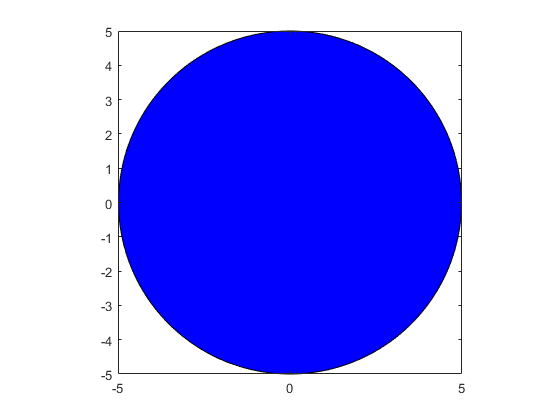

area = 78.5398

area = circle(5, 'b')

x =    5.0000 + 0.0000i   4.9975 + 0.1571i   4.9901 + 0.3140i   4.9778 + 0.4705i   4.9606 + 0.6267i   4.9384 + 0.7822i   4.9114 + 0.9369i   4.8796 + 1.0907i   4.8429 + 1.2434i   4.8015 + 1.3950i   4.7553 + 1.5451i   4.7044 + 1.6937i   4.6489 + 1.8406i   4.5888 + 1.9857i   4.5241 + 2.1289i   4.4550 + 2.2700i   4.3815 + 2.4088i   4.3037 + 2.5452i   4.2216 + 2.6791i   4.1354 + 2.8104i   4.0451 + 2.9389i   3.9508 + 3.0645i   3.8526 + 3.1871i   3.7506 + 3.3066i   3.6448 + 3.4227i   3.5355 + 3.5355i   3.4227 + 3.6448i   3.3066 + 3.7506i   3.1871 + 3.8526i   3.0645 + 3.9508i   2.9389 + 4.0451i   2.8104 + 4.1354i   2.6791 + 4.2216i   2.5452 + 4.3037i   2.4088 + 4.3815i   2.2700 + 4.4550i   2.1289 + 4.5241i   1.9857 + 4.5888i   1.8406 + 4.6489i   1.6937 + 4.7044i   1.5451 + 4.7553i   1.3950 + 4.8015i   1.2434 + 4.8429i   1.0907 + 4.8796i   0.9369 + 4.9114i   0.7822 + 4.9384i   0.6267 + 4.9606i   0.4705 + 4.9778i   0.3140 + 4.9901i   0.1571 + 4.9975i


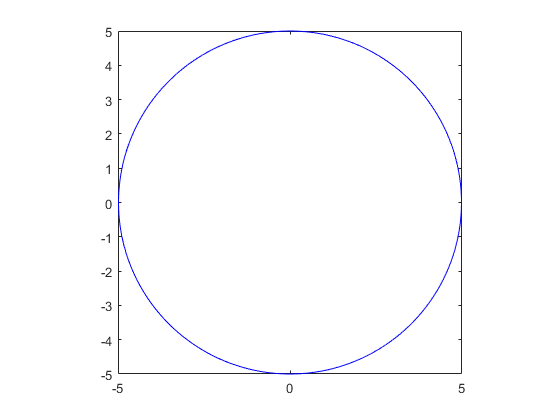

circle(5)

x =    5.0000 + 0.0000i   4.9975 + 0.1571i   4.9901 + 0.3140i   4.9778 + 0.4705i   4.9606 + 0.6267i   4.9384 + 0.7822i   4.9114 + 0.9369i   4.8796 + 1.0907i   4.8429 + 1.2434i   4.8015 + 1.3950i   4.7553 + 1.5451i   4.7044 + 1.6937i   4.6489 + 1.8406i   4.5888 + 1.9857i   4.5241 + 2.1289i   4.4550 + 2.2700i   4.3815 + 2.4088i   4.3037 + 2.5452i   4.2216 + 2.6791i   4.1354 + 2.8104i   4.0451 + 2.9389i   3.9508 + 3.0645i   3.8526 + 3.1871i   3.7506 + 3.3066i   3.6448 + 3.4227i   3.5355 + 3.5355i   3.4227 + 3.6448i   3.3066 + 3.7506i   3.1871 + 3.8526i   3.0645 + 3.9508i   2.9389 + 4.0451i   2.8104 + 4.1354i   2.6791 + 4.2216i   2.5452 + 4.3037i   2.4088 + 4.3815i   2.2700 + 4.4550i   2.1289 + 4.5241i   1.9857 + 4.5888i   1.8406 + 4.6489i   1.6937 + 4.7044i   1.5451 + 4.7553i   1.3950 + 4.8015i   1.2434 + 4.8429i   1.0907 + 4.8796i   0.9369 + 4.9114i   0.7822 + 4.9384i   0.6267 + 4.9606i   0.4705 + 4.9778i   0.3140 + 4.9901i   0.1571 + 4.9975i


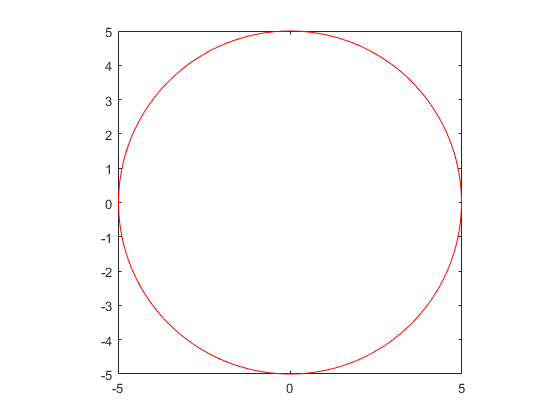

circle(5, 'r')

## `7.程序设计的基本步骤`

`（1）清晰地陈述你要解决的问题`

`（2）确定程序的输入输出`

`（3）为你的程序设计算法`

`（4）将算法转化为程序语言`

`（5）调试程序`

# `矩阵`

## `1.矩阵是什么？`

`(1)矩阵是线性代数的基本运算单元。`

`(2)矩阵含有M行N列数值。`

`(3)矩阵中的元素可以是实数或复数。`

`(4)矩阵相关的基本运算：加，减，内积，`

`* 矩阵的分类`

`（1）数值矩阵（实数和复数）`

`（2）符号矩阵`

`（3）特殊矩阵`

## `2.矩阵的构造`

`（1）实数数值矩阵的构造`

`方法一：由命令窗口直接输入。`

`    输入规则：`

`        同一行中不同元素用逗号或者空格符来分隔；`

`        空格个数不限；`

`        不同行用分号分隔或者分行输入；`

`        所有元素置于一对方括号之内；`

`        数据元素可以是表达式，MATLAB自动计算结果。`

`    例:输入矩阵A，B的值。`

A=[1, 2, 3, 4;
   5, 6, 7, 8;
   9, 10,11,12;
   13,14,15,16]

A =      1     2     3     4
     5     6     7     8
     9    10    11    12
    13    14    15    16


B=[1,sqrt(25),9,13
    2 6 10 7*2 
    3+sin(pi),7,11,15
    4, abs(-8),12,16]

B =      1     5     9    13
     2     6    10    14
     3     7    11    15
     4     8    12    16


`方法二：由m文件生成，`

`    规则：`

`        具体定义矩阵的规则见方法一。 `

`        m文件中的变量名称与文件名不能相同。`

`        否则会出现变量名与文件名的混乱。`

`    例题：由m文件输入矩阵的值。`

A=[1 2 3 4;5,6,7,8
    9,10,11,12;13 14 15 16]
B=[1,sqrt(25),9,13
    2 6 10 7*2 
    3+sin(pi),7,11,15
    4, abs(-8),12,16]

`方法三：由文本文件生成，`

`    规则：`

`        建立txt文件，直接用load调用此文件。`

`        txt文件中不含变量名称，文件名即为矩阵变量名。`

`        每行数值个数必须相等。`

`    例题：由文本文件输入矩阵的值。`

load matrix_txt.txt

`如何从excel中读取所需要的数据？`

`* excel读取函数xlsread`

`* dat  读取函数csvread`

`（2）复数数值矩阵的构造`

`构造方法同实数数值矩阵；将若干元素换成复数即可。`

A=[1 2 3 4;5,6,7,8; 1+2i,3+4i,2-8i,9-7i]

A =    1.0000 + 0.0000i   2.0000 + 0.0000i   3.0000 + 0.0000i   4.0000 + 0.0000i
   5.0000 + 0.0000i   6.0000 + 0.0000i   7.0000 + 0.0000i   8.0000 + 0.0000i
   1.0000 + 2.0000i   3.0000 + 4.0000i   2.0000 - 8.0000i   9.0000 - 7.0000i


`（3）符号矩阵的构造`

`构造方法同实数数值矩阵；将若干元素换成符号即可。`

syms x y z;
A=[x 2 3 4;5,y,7,8; 9 10 11 z]

$$A = \left(\begin{array}{cccc} x & 2 & 3 & 4\\ 5 & y & 7 & 8\\ 9 & 10 & 11 & z \end{array}\right)$$

`（4）特殊矩阵的构造`

a = magic(3)

a =      8     1     6
     3     5     7
     4     9     2


## `3.矩阵的修改`

`（1）部分扩充`

`    调用格式：D=[A;B C]`

`        A为原矩阵，B、C中包含要扩充的元素，D为扩充后的矩阵。`

`    例如： 扩充一个矩阵`

A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


D = [A;A]

D =      8     1     6
     3     5     7
     4     9     2
     8     1     6
     3     5     7
     4     9     2


% D = [A;A A]
D = [A;A;A]

D =      8     1     6
     3     5     7
     4     9     2
     8     1     6
     3     5     7
     4     9     2
     8     1     6
     3     5     7
     4     9     2


`（2）部分删除`

`   调用格式：A(:,n)=[]`

`            A(m,:)=[]`

`        A(:,n)=[]表示删除矩阵A的第n列；`

`        A(m,:)=[]表示删除矩阵A的第m行。`

`    例如：删除矩阵A的第二列和第三行。`

A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


A(:,2)=[]

A =      8     6
     3     7
     4     2


A(3,:)=[]

A =      8     6
     3     7


`（3）部分修改`

`    调用格式： A(m,n)=a；`

`              A(m,:)=[a]；`

`              A(:,n)=[b]；`

`        A(m,n)=a表示修改矩阵A的第（m，n）元素为a；`

`        A(m,:)=[a]表示修改矩阵A的第m行元素为a;`

`        A(:,n)=[b]表示修改矩阵A中第n列的元素为b。`

`例如：修改矩阵A的第二列元素和第三行元素。`

clear
A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


A(:,2)=[1]

A =      8     1     6
     3     1     7
     4     1     2


A(3,:)=[2]

A =      8     1     6
     3     1     7
     2     2     2


A(1, 1) = 5

A =      5     1     6
     3     1     7
     2     2     2


`（4）结构改变—左右翻转`

`    函数命令：fliplr`

`    调用格式：fliplr（A）`

`        fliplr（A）表示矩阵A行数不变，其元素左右翻转。`

`    例如：左右翻转矩阵A元素。`

A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


fliplr(A)

ans =      6     1     8
     7     5     3
     2     9     4


`（5）结构改变—上下翻转`

`    函数命令：flipud`

`    调用格式：flipud（A）`

`        flipud（A）表示矩阵A行数不变，其元素上下翻转。`

`    例如：上下翻转矩阵A元素。`

flipud(A)

ans =      4     9     2
     3     5     7
     8     1     6


`（6）结构改变—逆时针旋转`

`    函数命令： rot90`

`    调用格式： rot90（A）`

`              rot90（A，k）`

`        rot90（A,k）表示矩阵A元素逆时针翻转k个90度。`

`    例如：逆时针旋转矩阵A元素。`

rot90(A,2)

ans =      2     9     4
     7     5     3
     6     1     8


rot90(A,-2)

ans =      2     9     4
     7     5     3
     6     1     8


`（7）结构改变—按指定维数翻转矩阵`

`    函数命令：flipdim`

`    调用格式：flipdim(A，dim)`

`        flipdim(A,1)=flipud(A)`

`        flipdim(A,2)=fliplr(A)`

`（8）结构改变—平铺矩阵`

`    函数命令：repmat`

`    调用格式：repmat(A,m,n)`

`             repmat(A,[m,n])`

repmat(magic(3),2,1)

ans =      8     1     6
     3     5     7
     4     9     2
     8     1     6
     3     5     7
     4     9     2


`    提问：repmat(A,m,n)中A是一个数a时，表示什么？`

## `4.矩阵的变维`

`（1）：`

`    调用格式：B(:)=A(:)`

`    提问：B=A(:)表示什么？`

`        表示将矩阵A中的所有元素按列顺序合并成为一个向量。`

clear
A=[1 2 5 4; 6 7 0 1]

A =      1     2     5     4
     6     7     0     1


B=ones(4,2)

B =      1     1
     1     1
     1     1
     1     1


B(:)=A(:)

B =      1     5
     6     0
     2     4
     7     1


`    讨论几个问题：`

`        1.对B矩阵的维度有何要求？`

`        2.对B矩阵的元素值有何要求？`

`        2.如何变维？`

`（2）reshape`

`    调用格式：B=reshape(A,m,n)`

`        注意：使用reshape时，B中元素个数与A中相同！`

`    例如：已知A=[1:8],用矩阵A元素构成2×4维的矩阵B。`

A=[1:8]

A =      1     2     3     4     5     6     7     8


B=reshape(A,2,4)     

B =      1     3     5     7
     2     4     6     8


B=reshape(A,4,2)

B =      1     5
     2     6
     3     7
     4     8


## `5.矩阵的引用`

`引用格式``：`

`arrayName(m,n)；引用二维数组的第m行n列的元素`

`arrayName(m,:)；引用二维数组的第m行的所有列元素`

`arrayName(:,n)；引用二维数组的第n列的所有行元素`

`arrayName(m1:m2,n)；引用二维数组的第n列中m1至m2行的元素`

`arrayName(m,n1:n2)；引用二维数组的第m行中n1至n2列的元素`

`arrayName([m1 m2],n)；引用二维数组的第n列中m1行和m2行的元素`

`arrayName(m,[n1 n2])；引用二维数组的第m行中n1列和n2列的元`

`arrayName([m1 m2],[n1 n2])`

`问题：`

`    如何得到不同行也不同列的散列的若干个数据？`

`把握MATLAB中列序的概念！`

a = magic(3)

a =      8     1     6
     3     5     7
     4     9     2


b = a([2, 6])

b =      3     9


## `6.常用特殊矩阵`

`（1）空矩阵`

`        函数命令：[]`

`        调用格式：B=[]`

`（2）单位矩阵`

`        函数命令：eye`

`        调用格式：B=eye(n): 生成n×n单位阵`

`                 B=eye(m,n)：生成m×n单位阵         `

`                 B``=eye(size(A))：生成与A维度相同的单位阵`

`    例题: 若A=[1,2,3;2,3,4],求B=eye(size(A)) `

A=[1,2,3;2 3 4]  

A =      1     2     3
     2     3     4


B=eye(size(A))

B =      1     0     0
     0     1     0


B=eye(5,7) 

B =      1     0     0     0     0     0     0
     0     1     0     0     0     0     0
     0     0     1     0     0     0     0
     0     0     0     1     0     0     0
     0     0     0     0     1     0     0


B=eye(5)         

B =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


`（3）全零矩阵`

`        函数命令：zeros`

`        调用格式：B=zeros(n): 生成n×n零矩阵`

`                 B=zeros(m,n)：生成m×n零矩阵`

                 `B``=zeros(size(A))：生成与A维度相同的零矩阵      `

`    例题: 若A=[1,2,3;2,3,4],求B=zeros(size(A)) `

A=[1,2,3;2 3 4]  

A =      1     2     3
     2     3     4


B=zeros(size(A))

B =      0     0     0
     0     0     0


B=zeros(5,7) 

B =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


B=zeros(5)         

B =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


`（4）全1矩阵`

`        函数命令：ones`

`        调用格式：B=ones(n): 生成n×n全1矩阵`

`                 B=ones(m,n)：生成m×n全1矩阵`

                 `B``=ones(size(A))：生成与A维度相同的全1矩阵      `

`例题: 若A=[1,2,3;2,3,4],求B=ones(size(A)) `

A=[1,2,3;2 3 4]  
B=ones(size(A))
B=ones(5,7) 
B=ones(5)         

`（5）随机矩阵（0～1）`

`    函数命令：rand`

`    调用格式：B=rand：产生一个随机数 `

`              B=rand(n): 生成n×n随机矩阵`

`              B=rand(m,n)：生成m×n随机矩阵`

              `B``=rand(size(A))：生成与A维度相同的随机矩阵      `

`    例题: 若A=[1,2,3;2,3,4],求B=rand(size(A)) `

A=[1,2,3;2 3 4]  

A =      1     2     3
     2     3     4


B=rand(size(A))

B =     0.9027    0.4909    0.3377
    0.9448    0.4893    0.9001


B=rand(5,7)    

B =     0.3692    0.4039    0.5752    0.0154    0.6477    0.1890    0.7802
    0.1112    0.0965    0.0598    0.0430    0.4509    0.6868    0.0811
    0.7803    0.1320    0.2348    0.1690    0.5470    0.1835    0.9294
    0.3897    0.9421    0.3532    0.6491    0.2963    0.3685    0.7757
    0.2417    0.9561    0.8212    0.7317    0.7447    0.6256    0.4868


B=rand(5)         

B =     0.4359    0.8176    0.5328    0.6225    0.2305
    0.4468    0.7948    0.3507    0.5870    0.8443
    0.3063    0.6443    0.9390    0.2077    0.1948
    0.5085    0.3786    0.8759    0.3012    0.2259
    0.5108    0.8116    0.5502    0.4709    0.1707


`    例题: 生成区间[10，15]内均匀分布的3阶随机矩阵。 `

m=10;
n=15;
B=m+(n-m)*rand(3)         

B =    11.1383   14.6169   14.5244
   12.1785   12.1510   14.8987
   11.5555   10.9241   12.1943


`（6）随机矩阵（0均值单位方差正态分布）`

`    函数命令：randn`

`    调用格式：B=randn：产生一个随机数 `

`              B=randn(n): 生成n×n随机矩阵`

`              B=randn(m,n)：生成m×n随机矩阵`

              `B``=randn(size(A))：生成与A维度相同的随机矩阵      `

A=[1,2,3;2 3 4]  

A =      1     2     3
     2     3     4


B=randn(size(A))

B =    -1.5062   -0.1559   -0.2612
   -0.4446    0.2761    0.4434


B=randn(5,7) 

B =     0.3919   -0.3206   -1.0667   -1.5651   -0.7342   -0.2365    1.0001
   -1.2507    0.0125    0.9337   -0.0845   -0.0308    2.0237   -1.6642
   -0.9480   -3.0292    0.3503    1.6039    0.2323   -2.2584   -0.5900
   -0.7411   -0.4570   -0.0290    0.0983    0.4264    2.2294   -0.2781
   -0.5078    1.2424    0.1825    0.0414   -0.3728    0.3376    0.4227


B=randn(5)         

B =    -1.6702    0.3271   -0.9444    0.9111    0.2398
    0.4716    1.0826   -1.3218    0.5946   -0.6904
   -1.2128    1.0061    0.9248    0.3502   -0.6516
    0.0662   -0.6509    0.0000    1.2503    1.1921
    0.6524    0.2571   -0.0549    0.9298   -1.6118


`    例题: 生成均值为0.5，方差为0.05的3阶矩阵。 `

mu=0.5;
sigma=0.05;  
B=mu+sqrt(sigma)*randn(3)   

B =     0.4945    0.6927   -0.0559
    0.0642    0.5003    0.6300
    0.7282    0.4842    0.0098


`（7）魔方矩阵`

`    函数命令：magic`

`    调用格式：B=magic(n): 生成n×n魔方矩阵`

`          tip：魔方矩阵值行、列、正、反对角线之和相等的矩阵。且n!=2.`

`    例题: 求3阶魔方矩阵 `

B=magic(3)

`（8）稀疏矩阵`

`    函数命令：sparse`

`              full`

`    调用格式：B=sparse(A): 转换A矩阵为稀疏矩阵`

`              B=full(A):  转换A矩阵为完全矩阵      `

`    例题: 将完全矩阵F=[0 0 3;1 0 0;0 5 0]转化成稀疏矩阵S。`

F=[0 0 3;1 0 0;0 5 0]

F =      0     0     3
     1     0     0
     0     5     0


S=sparse(F)   

S =    (2,1)        1
   (3,2)        5
   (1,3)        3


F=full(S)  

F =      0     0     3
     1     0     0
     0     5     0


`Next：这几个函数生成什么矩阵？`

A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


diag(A)

ans =      8
     5
     2


triu(A)

ans =      8     1     6
     0     5     7
     0     0     2


tril(A)

ans =      8     0     0
     3     5     0
     4     9     2


## `7.特殊数组`

`（1）字符数组`

`    调用格式：`

`        s=‘string’         `

`        name=[‘str1’ ’str2’ ’str3’]`

s1=['who' 'are' 'you']

s1 = 'whoareyou'

s2=['I''m' 'Tin' 'Tin']

s2 = 'I'mTinTin'

s3=[s1 s2]

s3 = 'whoareyouI'mTinTin'

m=size(s1)

m =      1     9


n=size(s2)

n =      1     9


k=size(s3)

k =      1    18


`字符串转换方式一`

`    函数命令：char`

`    调用格式：S=char(T)`

`     表示将正整数矩阵转换成字符串矩阵S。`

T=[102 67 132 ; 50 95 78]

T =    102    67   132
    50    95    78


S=char(T)

S = 2×3 char 数组
    'fC'
    '2_N'


`字符串转换方式二`

`    函数命令：int2str, num2str`

`    调用格式：int2str(A)`

`             num2str(A,k)`

`             num2str(A,format)`

`        表示将数或矩阵转换成字符串或字符串矩阵。`

A=[1.2 6.7 3.2 ; 5.5 9.5 7.8];
B1=int2str(A)

B1 = 2×7 char 数组
    '1  7  3'
    '6 10  8'


B2=num2str(A)

B2 = 2×27 char 数组
    '1.2         6.7         3.2'
    '5.5         9.5         7.8'


% B1+B2;   

`字符串转换方式三`

`    函数命令：eval，str2num`

`    调用格式：eval(S)`

`             str2num(S)`

`        表示将字符串S转化为数值。`

a=[1 2]; 
w=[1 3];  
x=[1 2];
S= 'a.*sin(w.*x)'

S = 'a.*sin(w.*x)'

val=eval(S)   

val =     0.8415   -0.5588


str2num('3.14159e0')

ans = 3.1416

str2num(['1 2';'3 4'])  

ans =      1     2
     3     4


ans.*3

ans =      3     6
     9    12


`字符串比较`

`    函数命令：strcmp`

`    调用格式：strcmp(str1,str2)`

`        表示将两个字符串进行比较，相等时返回逻辑值为真。`

str1='bad';
str2='bad';
str3='dab';
strcmp(str1,str2)

ans = logical
   1


strcmp(str1,str3)

ans = logical
   0


`（2）结构数组`

`    提问：结构体的概念？`

`        如果让你统计全班同学基本信息，`

`        你的数据怎么组织？`

`    结构数组：`

`        是根据属性名组织起来的不同类型数据的集合。`

`    * 结构数组的引用：`

`       通过数组名和属性名来引用。`

`    函数命令：struct`

`        调用格式：sn=struct(‘filed1’,{},’filed2’,{},…)`

`例题：结构数组student有name和age两个属性。两组数据： `

`（liu，20）；（Wang，21）。并求student（1），student（2），student（2）.name。`

student=struct('name',{'Liu','Wang'},'Age',{'20','21'})

student = 包含以下字段的 1×2 struct 数组:
    name
    Age


student(1)

ans = 包含以下字段的 struct :
    name: 'Liu'
     Age: '20'


student(2)

ans = 包含以下字段的 struct :
    name: 'Wang'
     Age: '21'


student(2).name

ans = 'Wang'

`    如果想新增加域field怎么办？`

`    如果想给已有的域filed设置新的值怎么办？`

`例：建立学生档案结构体，并计算每个学生的总成绩。`

`    学号（number）：数值型`

`    姓名（name）：字符型`

`    英语考试成绩（English）：数值型`

`    数学考试成绩（Math）：数值型`

`    物理考试成绩（Physics）：数值型`

stud(1).number=input('please input number:');
stud(1).name=input('please input name:','s');
stud(1).math=input('please input math:');
stud(1).physics=input('please input physics:');
stud(1).english=input('please input english:');
stud(1).total=stud(1).math+stud(1).physics+stud(1).english;
stud(1)

ans = 包含以下字段的 struct :
     number: 6
       name: 'wang'
       math: 96
    physics: 86
    english: 99
      total: 281


n=input('please input n:');
for i=1:n
    stud(i).number=input('please input number:');
    stud(1).name=input('please input name:','s');
    stud(i).math=input('please input math:');
    stud(i).physics=input('please input physics:');
    stud(i).english=input('please input english:');
    stud(i).total=stud(i).math+stud(i).physics+stud(i).english;
end

`几个相关的函数命令：`

`    fieldnames，size，rmfield，getfield， setfield`

stud

stud = 包含以下字段的 struct :
     number: 6
       name: 'wang'
       math: '100'
    physics: 86
    english: 99
      total: 281


fieldnames(stud)  

ans = 6×1 cell 数组
    {'number' }
    {'name'   }
    {'math'   }
    {'physics'}
    {'english'}
    {'total'  }


size(stud)

ans =      1     1


rmfield(stud,'number') 

ans = 包含以下字段的 struct :
       name: 'wang'
       math: '100'
    physics: 86
    english: 99
      total: 281


stud=setfield(stud,{1,1},'math','100')

stud = 包含以下字段的 struct :
     number: 6
       name: 'wang'
       math: '100'
    physics: 86
    english: 99
      total: 281


str1=getfield(stud,{1,1},'math')

str1 = '100'

`•结构数组的嵌套`

`例题：建立嵌套的结构数组。`

a=struct('name','Mike','number','1000','score',struct('math','90','english','89','physics','97'));
a

a = 包含以下字段的 struct :
      name: 'Mike'
    number: '1000'
     score: [1×1 struct]


a(1).number

ans = '1000'

a(1).score

ans = 包含以下字段的 struct :
       math: '90'
    english: '89'
    physics: '97'


`（3）细胞数组`

`    提问：`

`        普通数组元素之间有什么关联？`

`        结构数组元素之间有什么关联？`

`        其特殊性在哪里？`

`        还有没有更特殊的可能性？`

`    函数命令：cell `

`细胞数组通常用{}创建，数据通过数组下标引用。`

B=cell(5,3);
B(1,1)={[1 4 3; 0 5 8; 7 2 9]};
B(1,2)={'Anne cat'};
B(2,1)={3+7i};
B(2,2)={0:pi/10:pi};
B{3,1}=[3 4 2;9 7 6;8 5 1];
B{3,2}='Anne Smith';
B{4,1}=3+7i;
B{4,2}=-pi:pi/10:pi;
B

B = 5×3 cell 数组
    {3×3 double        }    {'Anne cat'  }    {0×0 double}
    {[3.0000 + 7.0000i]}    {1×11 double }    {0×0 double}
    {3×3 double        }    {'Anne Smith'}    {0×0 double}
    {[3.0000 + 7.0000i]}    {1×21 double }    {0×0 double}
    {0×0 double        }    {0×0  double }    {0×0 double}


`* celldisp和cellplot方法`

B(1,1)={[1 4 3; 0 5 8; 7 2 9]};
B(1,2)={'Anne cat'};
B(2,1)={3+7i};
B(2,2)={0:pi/10:pi};
B

B = 5×3 cell 数组
    {3×3 double        }    {'Anne cat'  }    {0×0 double}
    {[3.0000 + 7.0000i]}    {1×11 double }    {0×0 double}
    {3×3 double        }    {'Anne Smith'}    {0×0 double}
    {[3.0000 + 7.0000i]}    {1×21 double }    {0×0 double}
    {0×0 double        }    {0×0  double }    {0×0 double}


celldisp(B)       

 
B{1,1} =
 
     1     4     3
     0     5     8
     7     2     9

 
 
B{2,1} =
 
   3.0000 + 7.0000i

 
 
B{3,1} =
 
     3     4     2
     9     7     6
     8     5     1

 
 
B{4,1} =
 
   3.0000 + 7.0000i

 
 
B{5,1} =
 
     []
 
 
B{1,2} =
 
Anne cat
 
 
B{2,2} =
 
         0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416

 
 
B{3,2} =
 
Anne Smith
 
 
B{4,2} =
 
  列 1 至 12

   -3.1416   -2.8274   -2.5133   -2.1991   -1.8850   -1.5708   -1.2566   -0.9425   -0.6283   -0.3142         0    0.3142

  列 13 至 21

    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416

 
 
B{5,2} =
 
     []
 
 
B{1,3} =
 
     []
 
 
B{2,3} =
 
     []
 
 
B{3,3} =
 
     []
 
 
B{4,3} =
 
     []
 
 
B{5,3} =
 
     []
 


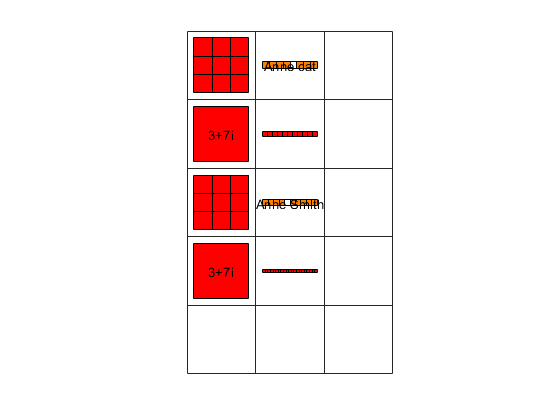

cellplot(B) 

`引用细胞数组元素：`

C=B{1,1}
C=B(1,1)    
D=B{1,1}(2,2)

`细胞数组的更新：`

% B(3,1)='No.1';    % (?)
B{3,2}='No.2'; 
B{3,3}='No.3';
B       
M=B(1:3,1:2)

`细胞数组的删除：`

B(:,3)=[]   
B{2,3}=[] 
B{2,2}(3)=0

`    ？尝试一下B{1}=[]  和B(1)=[] 。`

`细胞数组中reshape的使用：`

A=cell(3,4)
size(A)
B=reshape(A,6,2)
size(B)

`细胞数组和数值数组的转换`

`    例题：将二维细胞数组F转换为三维数值数据。`

F = cell(2,2)
F{1,1}=[1 2;3 4];
F{1,2}=[-1 0; 0 1];
F{2,1}=[7 8;4 1];
F{2,2}=[4i 3+2i;1-8i 5];
for k=1:4
    for i=1:2
        for j=1:2
            NUM(i,j,k)=F{k}(i,j);
        end
    end
end
F
NUM

`（4）结构细胞数组`

`将结构数组放入细胞数组中，可组成结构细胞数组。`

c_str=cell(1,2);
c_str{1}.label='12/2/94; 12/5/94';
c_str{1}.test=[47 52 55 48; 17 22 35 11];
c_str{2}.xdata=[-0.003 0.41 1.98 2.12 17.11];
c_str{2}.ydata=[-3 5 18 0 9];
c_str{2}.zdata=[0.6 0.8 1 2.2 3.4];
c_str{1}(1).test(2,2)

ans = 22

c_str

c_str = 1×2 cell 数组
    {1×1 struct}    {1×1 struct}


# `矩阵的运算`

## `1.矩阵的加减运算`

`    运算符：+，-`

`    运算规则：对应元素相加、减。`

`    例题：A=[1 2;3,4],B=[5 6;7 8],`

`         求X1=A+B; X2=A-B; X3=A+3; X4=B-4。`

A=[1,2;3,4]

A =      1     2
     3     4


B=[5 6;7 8] 

B =      5     6
     7     8


X1=A+B

X1 =      6     8
    10    12


X2=A-B

X2 =     -4    -4
    -4    -4


X3=A+3

X3 =      4     5
     6     7


X4=B-4

X4 =      1     2
     3     4


## `2.矩阵的乘法运算`

`    运算符： *：矩阵乘法`

`            .*：矩阵对应元素相乘（数组运算）`

`    例题：A=[1 2 3; 4,5,6],B=[5 6;7 8;9 10]`

`        求X1=A*B; X2=A*2; X3=A.*B; X4=A.*2。`

A=[1,2,3; 4 5 6]

A =      1     2     3
     4     5     6


B=[5 6;7 8;9 10]

B =      5     6
     7     8
     9    10


X1=A*B;X1=B*A;
X2=2*A

X2 =      2     4     6
     8    10    12


% X3=A.*B  
X4=A.*2

X4 =      2     4     6
     8    10    12


`例题：A=[1 2 3; -2 0 0;1 0 1;-1 2 -3],B=[-1 3;-2 2;2  1],求A*B`

A=[1 2 3; -2 0 0;1 0 1;-1 2 -3],B=[-1 3;-2 2;2  1]

A =      1     2     3
    -2     0     0
     1     0     1
    -1     2    -3


B =     -1     3
    -2     2
     2     1


A*B

ans =      1    10
     2    -6
     1     4
    -9    -2


% B*A 

## `3. 矩阵的除法运算`

`运算符：     `

`    \   ：矩阵左除`

`    /   : 矩阵右除`

`    ./  ：矩阵点右除（数组运算）`

`    .\  ：矩阵点左除（数组运算）`

`提示：     `

`* x=A\B是方程A*x=B的解;`

`* x=B/A是方程x*A=B的解。`

`* 若A为非奇异矩阵，则A\B和B/A可如下获得：`

`        A\B=inv(A)*B         B/A=B*inv(A)`

`例题：A=[1 0 3; 4 13 6;7 4 9],B=[4;7;1]`

`           求X1=A\B；X2=B/A；X3=A./B`

A=[1 0 3; 4 13 6;7 4 9],B=[4;7;1]

A =      1     0     3
     4    13     6
     7     4     9


B =      4
     7
     1


X1=A\B

X1 =    -3.1591
    0.4091
    2.3864


% X2=B/A
X3=A./B

X3 =     0.2500         0    0.7500
    0.5714    1.8571    0.8571
    7.0000    4.0000    9.0000


X4=A./2

X4 =     0.5000         0    1.5000
    2.0000    6.5000    3.0000
    3.5000    2.0000    4.5000


`例如：哥哥弟弟年龄问题。`

`    哥哥比弟弟大19岁，哥哥年龄是弟弟的3倍还多1，问：哥哥和弟弟的年龄分别是多少？`

`解答方法：`

`    g-3d=1； g-d=19；`

`用矩阵方式解答：`

A=[1,-3;1,-1],B=[1;19]

A =      1    -3
     1    -1


B =      1
    19


X1=A\B

X1 =     28
     9


## `4.矩阵的乘方运算`

`运算符： `

`    ^: A^p表示矩阵的乘方。`

`    .^: A.^B表示矩阵A的数量乘方。`

`（1）^的运算规则：     `

`A为方阵，p为>0的整数时，A^p表示A自乘p次；p为<0的整数时，A^p表示A-1的|p|次方`

`例题：A=[1 0 3; 4 13 6;7 4 9], 求A^2`

A=[1 0 3; 4 13 6;7 4 9]

A =      1     0     3
     4    13     6
     7     4     9


A^2      

ans =     22    12    30
    98   193   144
    86    88   126


`（2）.^的运算规则：`

`A.^p 表示矩阵中每个元素的p次乘方。`

`维度相同的A、B矩阵求A.^B，表示矩阵A中元素对矩阵B中的对应元素求幂。结果矩阵与原矩阵维度相同。`

`例题：A=[1 0 3; 4 13 6;7 4 9] ，B=[1,2,3; 4,5,6; 7,8,9]`

`            求X1=A.^2，X2=A.^B`

A=[1 0 3; 4 13 6;7 4 9]

A =      1     0     3
     4    13     6
     7     4     9


B=[1 2 3; 4 5 6;7 8 9]

B =      1     2     3
     4     5     6
     7     8     9


X1=A.^2

X1 =      1     0     9
    16   169    36
    49    16    81


X2=A.^B

X2 =            1           0          27
         256      371293       46656
      823543       65536   387420489


## `5.矩阵的转置`

`运算符：'`

`运算规则：`

`（1）若矩阵A的元素为实数、则A’返回A的转置；`

`（2）若矩阵A为复数矩阵，则A’中的元素由A对应元素的共轭复数构成。`

`例题：A=[1 0 3; 4 13 6;7 4 9]；B=[1 2 3; 4 5 6;7 8 9+9i]`

`            求X1=A’ , X2=B’`

A=[1 0 3; 4 13 6;7 4 9]
B=[1 0 3; 4 13 6;7 4 9+9i]
X1=A'
X2=B'

## `6.矩阵的逆`

`运算符：inv`

`调用格式：B=inv(A)`

`例题： G=[1 2 0; 2 5 -1;4 10 -1], 求G的逆，并验证之。`

G=[1 2 0; 2 5 -1;4 10 -1]
X=inv(G)
DW1=G*X
DW2=X*G

## `7.矩阵的特征值`

`运算符：eig`

`调用格式：eig(A)`

`例题：求矩阵A的特征值。其中A=[1 0 0;0 2 0;0 0 3]。`

A=[1 0 0;0 2 0; 0 0 3]
eig(A)

## `8.求矩阵的特征多项式`

`运算符：poly`

`调用格式：poly(A)`

`例题：求矩阵A的特征多项式。其中A=[1 2 0;2 5 -1;4 10 -1]。`

A=[1 2 0;2 5 -1;4 10 -1] 

A =      1     2     0
     2     5    -1
     4    10    -1


poly(A)

ans =     1.0000   -5.0000    5.0000   -1.0000


## `9.求矩阵的秩`

`运算符： rank`

`调用格式：rank(A)`

`例题：求矩阵A的秩。其中A=[1 2 3;4 5 6]。`

A=[1 2 3;4 5 6] 

A =      1     2     3
     4     5     6


rank(A)

ans = 2

## `10.求矩阵元素的个数`

`运算符：numel`

`调用格式：numel(A)`

`例题：求矩阵A的个数。其中A=[1 2 3;4 5 6]。`

A=[1 2 3;4 5 6] 

A =      1     2     3
     4     5     6


numel(A)

ans = 6

## `11.方阵的行列式`

`运算符：det`

`调用格式：det(A)`

`例题：求方阵A的行列式的值。其中A=[1 1 0; 0 0 2； 0 5 -1]。`

A=[1 1 0; 0 0 2;0 5 -1]

A =      1     1     0
     0     0     2
     0     5    -1


det(A)

ans = -10

## `12 方阵的迹`

`运算符：trace`

`调用格式：trace(A)`

`例题：求方阵A迹。其中A=[1 1 0; 0 0 2； 0 5 -1]。`

A=[1 1 0; 0 0 2;0 5 -1]

A =      1     1     0
     0     0     2
     0     5    -1


trace(A)

ans = 0

# `矩阵的关系运算和逻辑运算`

## `1.关系运算符`

`    ==，~=，>, >=, <,  <=`

`    主要用来对矩阵与数，矩阵与矩阵进行比较，返回二者关系的，由数0和数1组成的矩阵，0和1分别表示不满足和满足指定关系。`

A=[1 2;2 3]

A =      1     2
     2     3


B=A==1

B = 2×2 logical 数组
   1   0
   0   0


B=A==2

B = 2×2 logical 数组
   0   1
   1   0


B=A==3

B = 2×2 logical 数组
   0   0
   0   1


C=[2 2; 2 2]

C =      2     2
     2     2


B=C==A

B = 2×2 logical 数组
   0   1
   1   0


## `2.逻辑运算符`

`    & , | , ~,  xor`

`    MATLAB中，所有非零数值均被认为真，零为假。在判断结果中，判断为真输出1，判断为假输出0。`

A=[1 1; 0 1]

A =      1     1
     0     1


b=0;
B=[0 1 ;0 0 ]

B =      0     1
     0     0


C1=A&b

C1 = 2×2 logical 数组
   0   0
   0   0


C2=A|b      

C2 = 2×2 logical 数组
   1   1
   0   1


C3=xor(A,B)

C3 = 2×2 logical 数组
   1   0
   0   1


## `3.逻辑函数`

`    all：判断是否所有元素为非零值；`

`    any：判断是否存在一个元素为非零值；`

`    exist：查看变量或函数是否存在； `

`    find：找出向量或矩阵中非零元素的位置标识；`

`    isempty：判断矩阵是否为空矩阵；`

`    isequal: 判断几个对象是否相等；`

`    isnumeric:判断对象是否为数值型。`

a=[1 3 5]

a =      1     3     5


A=[1 2 3 ; 0 4 5 ]

A =      1     2     3
     0     4     5


B1=all(a)

B1 = logical
   1


B2=all(A)

B2 = 1×3 logical 数组
   0   1   1


B2 = all(all(A))

B2 = logical
   0


B3=all(A,2)

B3 = 2×1 logical 数组
   1
   0



a=[0 3 0]

a =      0     3     0


A=[1 0 3;0 0 5]

A =      1     0     3
     0     0     5


B1=any(a)

B1 = logical
   1


B2=any(A)

B2 = 1×3 logical 数组
   1   0   1


B3=any(A,2)

B3 = 2×1 logical 数组
   1
   1



a1=exist('work')

a1 = 0

a2=exist('filtdes')

a2 = 2

a3=exist('c:\windows')

a3 = 7


A=[1.2 0 3.5 ; 0 0 5.4]

A =     1.2000         0    3.5000
         0         0    5.4000


k=find(A)

k =      1
     5
     6


[m,n]=find(A)

m =      1
     1
     2


n =      1
     3
     3


[m,n,v]=find(A)

m =      1
     1
     2


n =      1
     3
     3


v =     1.2000
    3.5000
    5.4000



A=[0.34 0.6]

A =     0.3400    0.6000


B=[0.34 0.6]

B =     0.3400    0.6000


C=['who']

C = 'who'

isequal(A, B)

ans = logical
   1


isequal(A, C)

ans = logical
   0



A=[0.34 0.6]

A =     0.3400    0.6000


B=[1+2i 0.6+3i]

B =    1.0000 + 2.0000i   0.6000 + 3.0000i


C=['who']

C = 'who'

isnumeric(A)

ans = logical
   1


isnumeric(B)

ans = logical
   1


isnumeric(C)

ans = logical
   0


# `多项式`

`    形如`$P\left(x\right)=a_0 x^n +a_1 x^{n-1} +\ldotp \ldotp \ldotp +a_{n-1} x+a_n$`的式子,MATLAB中，多项式用行向量表示：`$P=\left\lbrack a_0 \;a_1 \;\ldotp \ldotp \ldotp a_{n-1} \;a_n \right\rbrack$

## `1.多项式的构造`

`* 直接输入法`

A=[1 3 5 7 9 0 0]

`* 使用poly方法`

`例题：已知向量A=[1 -34 -80 0 0]，P(x)=(x-1)(x+34)(x+80)(x-0)(x-0)`

`用此向量构造一多项式并显示结果。`

A=[1 -34 -80 0 0 ]
poly(A)

`* 使用poly2sym方法`

`例题：已知向量A=[1 -34 -80 0 0]，P(x)=(x-1)(x+34)(x+80)(x-0)(x-0)`

`用此向量构造一多项式并显示结果。`

A=[1 -34 -80 0 0 ]
PA=poly(A)
poly2sym(PA)

## `2.多项式的运算`

`* 多项式的加减运算`

`运算符：+  -`

`注意事项：`

`（1）具有相同的阶次；`

`（2）如果阶次不同，低阶的多项式必须用零填补至高阶多项式的阶次。`

`例题：求两个多项式a(x)=5x4+ 4x3+3X2+2x+1; b(x)=3x2+1的和。`

a=[5 4 3 2 1]
b=[3 0 1]
% a+b
c=a+[0 0 b]

`* 多项式的乘法运算`

`调用函数：conv(a,b)`

`例题：求两个多项式a(x)=5x4+ 4x3+3X2+2x+1 ;b(x)=3x2+1的积。`

a=[5 4 3 2 1];
b=[3 0 1]
c=conv(a,b)

`* 多项式的除法运算`

`调用函数：deconv(a,b)`

`调用格式：[div,rest]=deconv(a,b)`

`    div:  商多项式`

`    rest: 余数多项式`

`例题:求两个多项式a(x)=5x4+ 4x3+3X2+2x+1 ;b(x)=3x2+1的商。`

a=[5 4 3 2 1]
b=[3 0 1]
[div,rest]=deconv(a,b)

`* 多项式的微分运算`

`调用函数：polyder`

`调用格式：B=polyder(A)`

`例题：求多项式`$p\left(x\right)=2x^4 -6x^3 +3x^2 +7$`的微分。`

p=[2 -6 3 0 7]
q=polyder(p)

`* 多项式求根`

`调用函数：roots`

`调用格式：X=roots(A)`

`例题：求多项式`$p\left(x\right)=2x^4 -6x^3 +3x^2 +7$`的根。`

p=[2 -6 3 0 7]
X=roots(p)

`* 多项式求值`

`调用函数：polyval ，polyvalm`

`调用格式：B=polyval(A,a )`

`         B=polyvalm(A,M)`

`例题:求多项式`$p\left(x\right)=2x^4 -6x^3 +3x^2 +7$`当x=1时的值。`

p=[2 -6 3 0 7]
B=polyval (p,1)

`例题:求多项式`$p\left(x\right)=2x^4 -6x^3 +3x^2 +7$`当x=[1 2 ;3 4]时的值。`

p=[2 -6 3 0 7]
M=[1 2 ;3 4 ]
B=polyvalm(p,M)

`例题:将表达式`$\left(x-4\right)\left(x+5\right)\left(x^2 -6x+9\right)$`展开为多项式，并求其对应的一元n次方程的根。`

p=conv([1 -4],conv([1 5],[1 -6 9 ]))
px=poly2sym(p,'x')
x=roots(p)

`例题:已知一元四次方程对应的四个根为-5，4，3，3。求这个方程所对应的表达式原型。`

x=[-5 4 3 3]
p=poly(x)
px=poly2sym(p,'x')


# `函数脚本`

% 脚本名称：arith_1.m
% 脚本功能：任意输入一个正整数，如果是偶数，用2除
%                              如果是奇数，用3乘再加1
%           反复重复这个过程，直到得到的数为1
%           将依次得到这个数的数列返回
% 脚本作者：左手Python右手R
% 创建时间：2018年07月12日19:32
% 修改时间：

function y = arith_1(x)
    % 健壮性判断
    if round(x) ~= x
        error('Please enter an integer!');
    end
    
    k = 1;                  % 赋序列初始索引
    y(k) = x;               % 输入
    while (x~=1) 
        k = k + 1;          % 索引递增
        if rem(x, 2) == 0   % 求余
            x = x/2;        % 执行偶数对应操作
            y(k) = x;
        else 
            x = x*3 + 1;    % 执行奇数对应操作
            y(k) = x;
        end
    end
end

function y = mainFunc(x)
    y = x*subFunc(x);
end

function u = subFunc(w)
    u = w/2;
end

function [y] = sin_cos(x)
%SIN_COS a small calculation
%   cal cos then sin and return
%   input: x
%   output: y

y = sin(cos(x));

end

function out = sample(a, b)
fprintf('In Sample, before compute: a = %f, b = %f \n', a, b);
a = b + 2*a;
b = a * b;
out = [a  b];
fprintf('In Sample, after compute: a = %f, b = %f\n', a, b);
end

function s = circle(r, c)
%CIRCLE plot a circle of radii r, with color c

% input: r, radius
%        c, color
% output: s, area
if nargin == 1
    c = 'b';
end
clf
t = 0:pi/100:2*pi;
x = r*exp(i*t)
if nargout == 0
    plot(x, c)
else
    s = pi*r*r;
    fill(real(x), imag(x), c)    
end
axis('square')
end